## 分析阻尼项对于主轴环的影响, -k omega

% k_W = 0
clc
ulogOBJ = ulogreader("HILSimData\stable3\log_0_2021-6-30-08-02-16.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{35};
q = attitude.q;
maxi = size(q,1);
for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_1 = N3(:,3);
clear msg N3 q ulogOBJ attitude i maxi

% k_W = 0.01
clc
ulogOBJ = ulogreader("HILSimData\stable3\log_0_2021-6-30-08-24-52.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{36};
q = attitude.q;
maxi = size(q,1);
for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_2 = N3(:,3);
clear msg N3 q ulogOBJ attitude i maxi

% k_W = 0.02
clc
ulogOBJ = ulogreader("HILSimData\stable3\log_1_2021-6-30-08-26-32.ulg");
msg = readTopicMsgs(ulogOBJ);
attitude = msg.TopicMessages{32};
q = attitude.q;
maxi = size(q,1);
for i=1:maxi
    N3(i,:) = quad2dcm(q(i,:));
end
h3_3 = N3(:,3);
clear msg N3 q ulogOBJ attitude i maxi

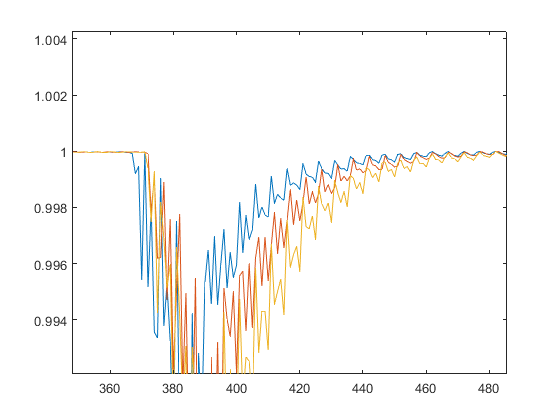

figure(1)
clf
plot(h3_1(1:1670))

hold on
plot(h3_2(19:1704))

hold on
plot(h3_3(90:1666))